# Homework #2

## Kurt Delegard

## PHYS 434 AB

Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice sum to seven)?

For each die, one has a 1/6 chance of rolling any of the 6 values. Following the rule that $P\left(A\;\mathrm{and}\;B\right)=P\left(A\right)*P\left(B\right)$, and given that for any value of either die $P\left(A\right)=P\left(B\right)=\frac{1}{6}$, we can determine that any combination of two die values (e.g. 2 and 6, 1 and 3, 5 and 5) will have a 1/36 chance of occuring.

There is only one combination that will yield two ones: throwing two ones. No other combination of die values will sum to 2. Thus we can infer that the probability of throwing snake eyes is 1/36.

However, there are several ways to roll two dice such that their values sum to 7: 

1 + 6

ans = 7

2 + 5

ans = 7

3 + 4

ans = 7

4 + 3

ans = 7

5 + 2

ans = 7

6 + 1

ans = 7

Since there are three options that yield a sum of seven, we can say that the probability of rolling a sum of seven is 6/36 = 1/6.

Therefore, it is more probable to roll a sum of seven than it is to roll snake eyes. The ratio of their probabilities is 

(1/6) / (1/36)

ans = 6

2. Probability of sum of 2 6-sided dice

Each die has values {1 2 3 4 5 6}. 

Each of these values has probability [1/6 1/6 1/6 1/6 1/6 1/6].

A system of two dice has values {2 3 4 5 6 7 8 9 10 11 12}.

To find the probabilities for each of these values, one can use the discrete convolution equation: $P_{A+B} \left(x\right)=\sum_z P_A \left(z\right)*P_B \left(x-z\right)$.

x can take any value from 1-12 from our system of two dice, while z can range from 1-6 for either of the individual dice.

For example, we will find the probability of rolling a sum of 1:


$$P_{A+B} \left(1\right)=\sum_z P_A \left(z\right)*P_B \left(1-z\right)$$


Now we will sum over all values of z, starting with 1:


$$P_A \left(1\right)*P_B \left(1-1\right)=P_A \left(1\right)*P_B \left(0\right)=0$$


There is zero probability of rolling a zero on any die. Furthermore, if we increase z any more, we will end up with a term $P_B \left(-1\right)$; there is also zero probability of rolling any negative number. Therefore, the probability of rolling a sum of 1 with two dice is zero.

For two dice:


$$P_{A+B} \left(2\right)=\sum_z P_A \left(z\right)*P_B \left(2-z\right)$$


Summing over values of z, starting with 1:


$$P_A \left(2\right)*P_B \left(2-1\right)=P_A \left(2\right)*P_B \left(1\right)=\frac{1}{6}*\frac{1}{6}=\frac{1}{36}$$



$$P_A \left(2\right)*P_B \left(2-2\right)=P_A \left(2\right)*P_B \left(0\right)=0$$


The sum terminates after 1 iteration - the probability of rolling a sum of 2 is 1/36.

The rest of these probabilities can be calculated by hand, but here I will calculate them individually using for loops:

prob = 1/6;
prob_sums = zeros(1, 13);

for x = 2:12
    for z = 1:6
        if x-z > 0 & x-z <= 6
            prob_sums(x) = prob_sums(x) + prob*prob;
        else 
            continue
        end
    end
end
disp(prob_sums);

         0    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278         0



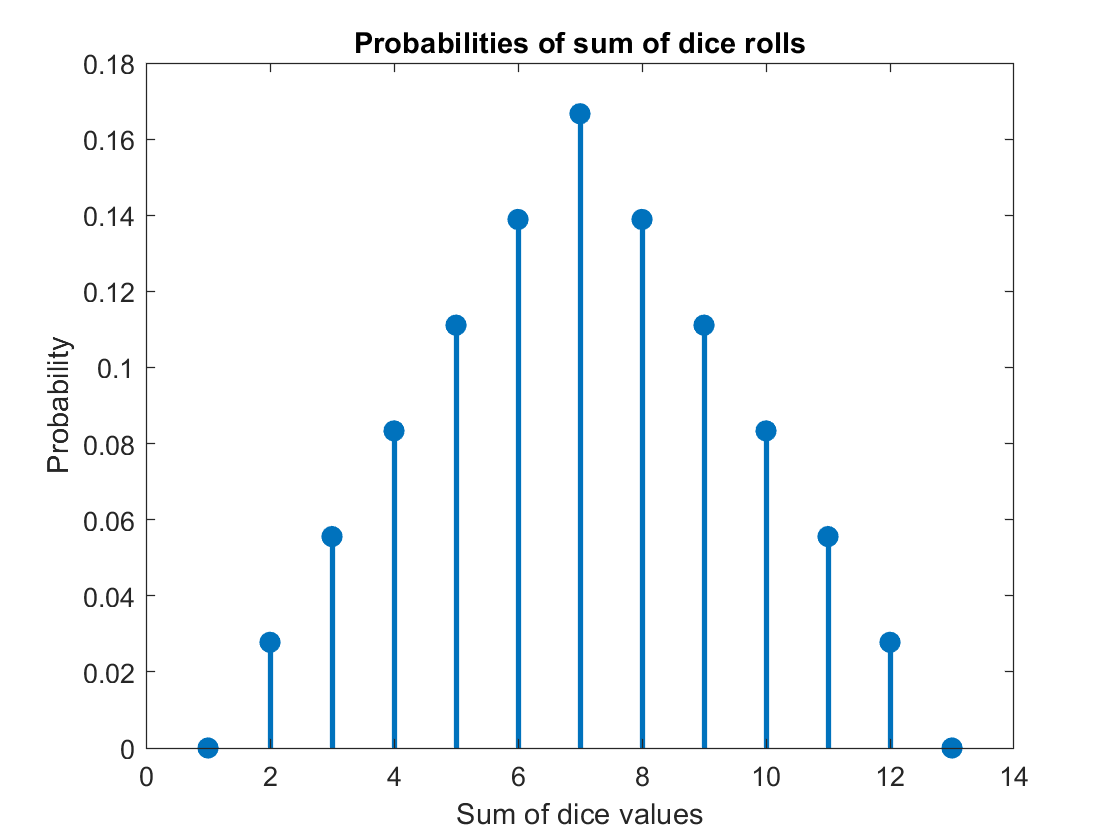


clf;
stem(1:13, prob_sums, 'filled', 'linewidth', 2);
title('Probabilities of sum of dice rolls');
xlabel('Sum of dice values');
ylabel('Probability')

We can also determine the probabilities with the use of the conv() command:

p1 = 1/6 * ones(1, 6);
p2 = 1/6 * ones(1, 6);
p_total = conv(p1, p2)

p_total =     0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278


This row vector shows the probabilities associated with dice values summing to 2 through 12, respectively.

3. Mean and variance

Here we will determine the mean and variance of this distribution:

avg = mean(p_total)

avg = 0.0909

This result is incorrect. The mean() command assumes the vector it is taking the average of is a list of unweighted values. However, the conv() command we used earlier assumes that the vector uses evenly spaced weights.

To take the average of the distribution, we simply sum the products of the probabilities with their associated values:

values = 2:12;
weighted_values = values .* p_total;
avg_weighted = sum(weighted_values)

avg_weighted = 7

The average value of this distribution is 7. This agrees with what we already know - 7 is the most probable outcome when throwing two dice and summing the values together.

The variation is given by $\sigma^2 =\frac{1}{N}\sum_{i=1}^N {\left(x_i -\mu \right)}^2$, or by taking the mean of the squares of the differences between the mean and the values. For example, for one die with an average roll of 3.5:

xs = 1:6;
differences = xs - 3.5;
diffs_squared = differences .^ 2;
variance = (mean(diffs_squared))

variance = 2.9167

Since each die roll is independent of each other, we can infer that the variance for two dice is twice that of the variance for one die:

variance_2dice = 2 * variance

variance_2dice = 5.8333

4. Convolution of 10 dice

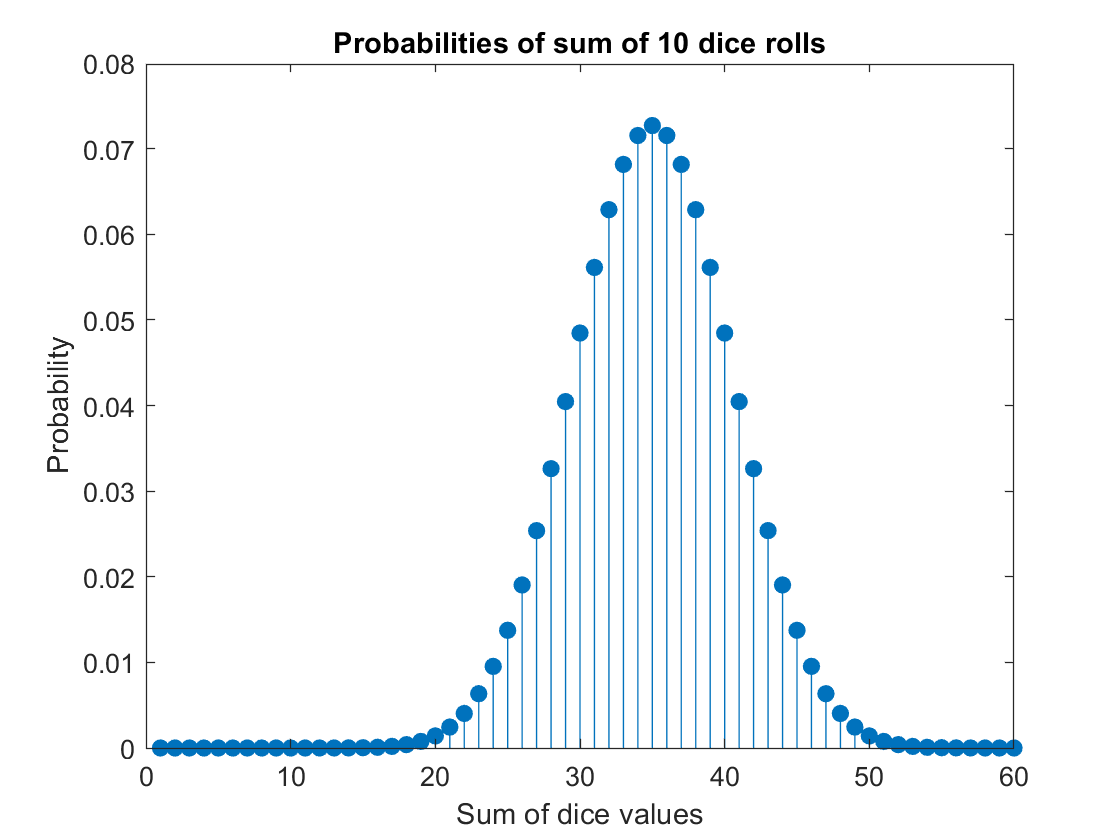

clear;

prob_1 = 1/6 * ones(1, 6);
probs_10 = prob_1;
for aa = 1:9
    probs_10 = conv(prob_1, probs_10);
end
probabilities = zeros(1, 60);
probabilities(10:60) = probs_10;
clf;
stem(1:60, probabilities, 'filled');
title('Probabilities of sum of 10 dice rolls');
xlabel('Sum of dice values');
ylabel('Probability');

To find the average value of 10 dice throws (not the sum of 10 dice rolls), find the average value after throwing a six-sided die 10 times. We can create a histogram showing the average value of 10 throws and the approximate count rate for each of these averages.

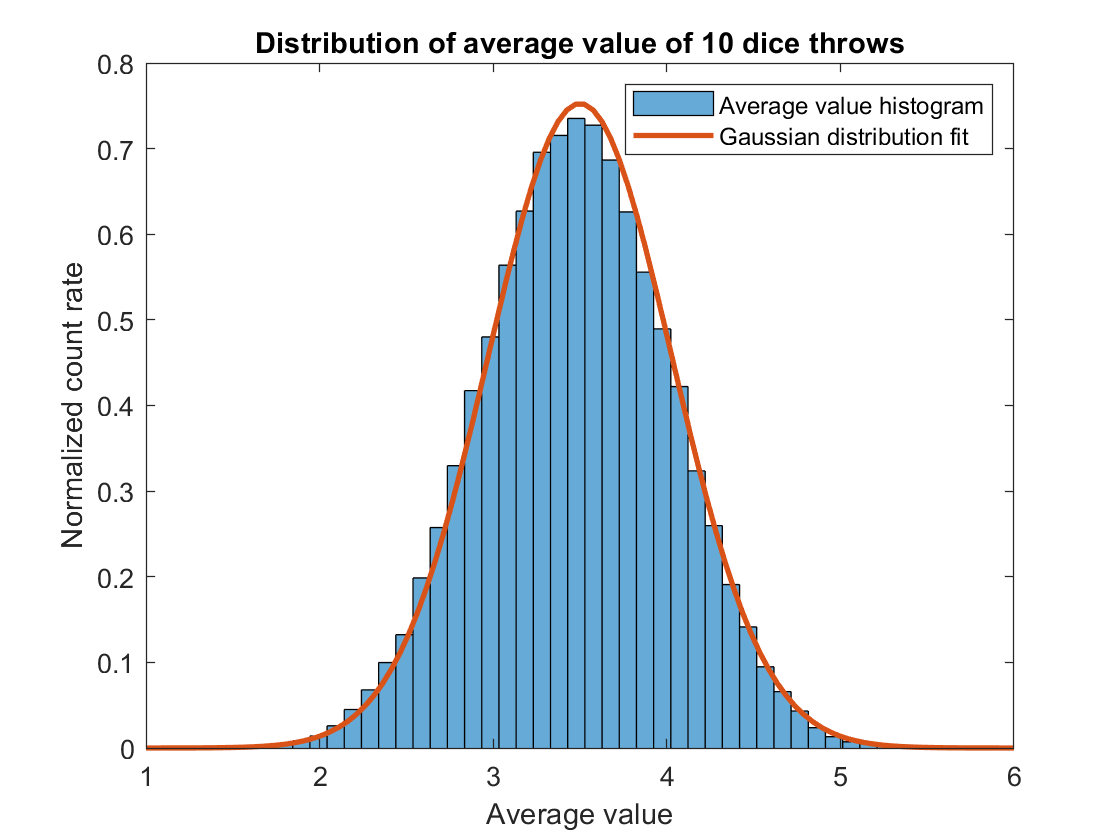

samples = 100000;
averages = zeros(1, samples);
for ii = 1:samples
    ten_throws = randi([1 6], 1, 10);
    averages(ii) = mean(ten_throws);
end

clf;
histogram(averages, 44, 'Normalization', 'pdf'), hold on;
title('Distribution of average value of 10 dice throws');
xlabel('Average value');
ylabel('Normalized count rate');
xs = linspace(1, 6, 100);
pd = makedist("Normal","mu", 3.5 ,"sigma", 0.53 );
plot(xs,pdf(pd,xs),"LineWidth",2);
legend('Average value histogram', 'Gaussian distribution fit')

It is hard to tell whether this distribution is truly Gaussian in nature. One defining characteristic of Gaussian distributions is that they take on a parabolic shape when plotted on a logarithmic scale:

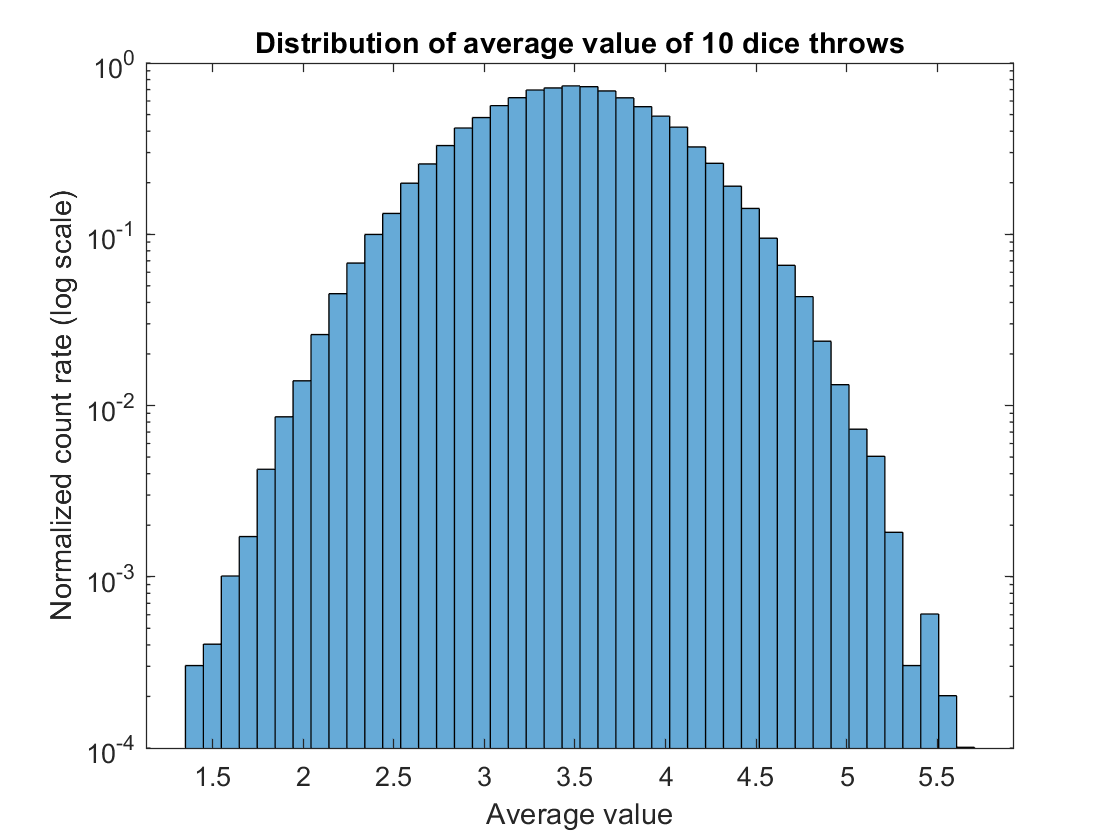

clf;
histogram(averages, 44, 'Normalization', 'pdf'), hold on;
title('Distribution of average value of 10 dice throws');
xlabel('Average value');
ylabel('Normalized count rate (log scale)');

%plot(xs,pdf(pd,xs),"LineWidth",2);
%legend('Average value histogram', 'Gaussian distribution fit', 'location', 'southeast')
set(gca,'YScale','log')

Yes, this distribution appears to be approximately Gaussian. 

The more dice we add to the system, the more this distribution will approach a Gaussian distribution. This is because for each die that is added, the original system is convolved, or averaged, with itself. According to the Central Limit Theorem, after averaging a distribution several times, its shape will approach that of a Gaussian distribution.

Here is an example of a system with 3 dice vs. a system with 40 dice:

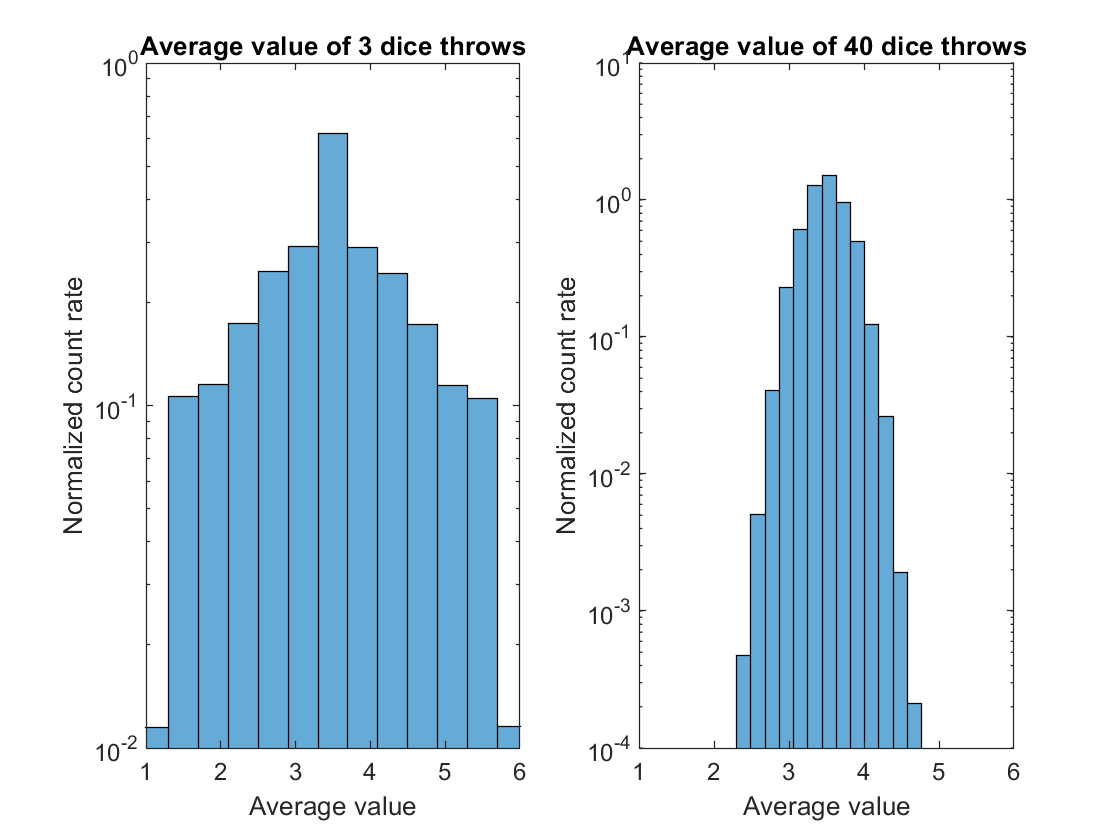

clear;
clf;
subplot(1, 2, 1);
samples = 100000;
averages = zeros(1, samples);
for ii = 1:samples
    three_throws = randi([1 6], 1, 3);
    averages(ii) = mean(three_throws);
end

histogram(averages, 13, 'Normalization', 'pdf'), hold on;
title('Average value of 3 dice throws');
xlabel('Average value');
ylabel('Normalized count rate');
set(gca,'YScale','log')
xlim([1 6])
subplot(1, 2, 2);
samples = 100000;
averages = zeros(1, samples);
for ii = 1:samples
    forty_throws = randi([1 6], 1, 40);
    averages(ii) = mean(forty_throws);
end

histogram(averages, 13, 'Normalization', 'pdf'), hold on;
title('Average value of 40 dice throws');
xlabel('Average value');
ylabel('Normalized count rate');
set(gca,'YScale','log')
xlim([1 6])

5. Central Limit Theorem

The sum or average of a Gaussian distribution is also Gaussian. We can prove this by convolving a set of normally distributed data with itself:

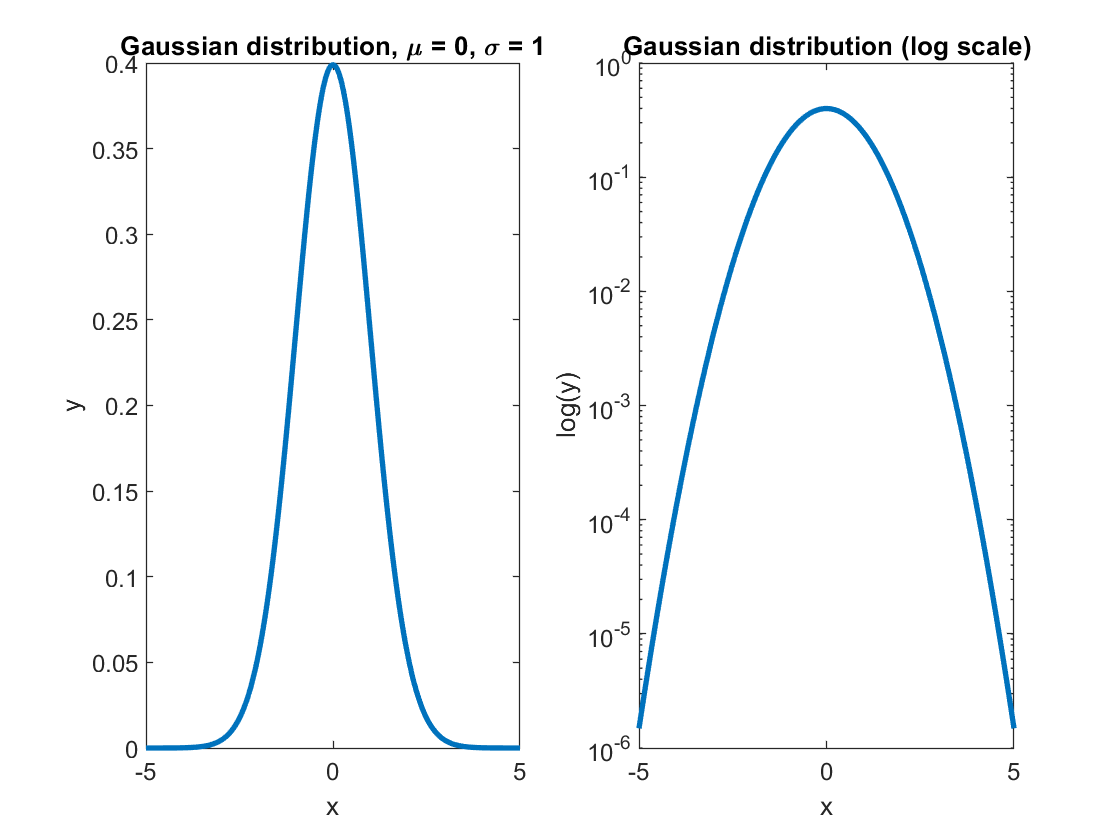

clear;
clf;

xs = linspace(-5, 5, 1000);
ys = normpdf(xs, 0, 1);

subplot(1, 2, 1);
plot(xs, ys, 'linewidth', 2);
title('Gaussian distribution, {\mu} = 0, {\sigma} = 1');
xlabel('x');
ylabel('y');

subplot(1, 2, 2);
semilogy(xs, ys, 'linewidth', 2);
title('Gaussian distribution (log scale)');
xlabel('x');
ylabel('log(y)');

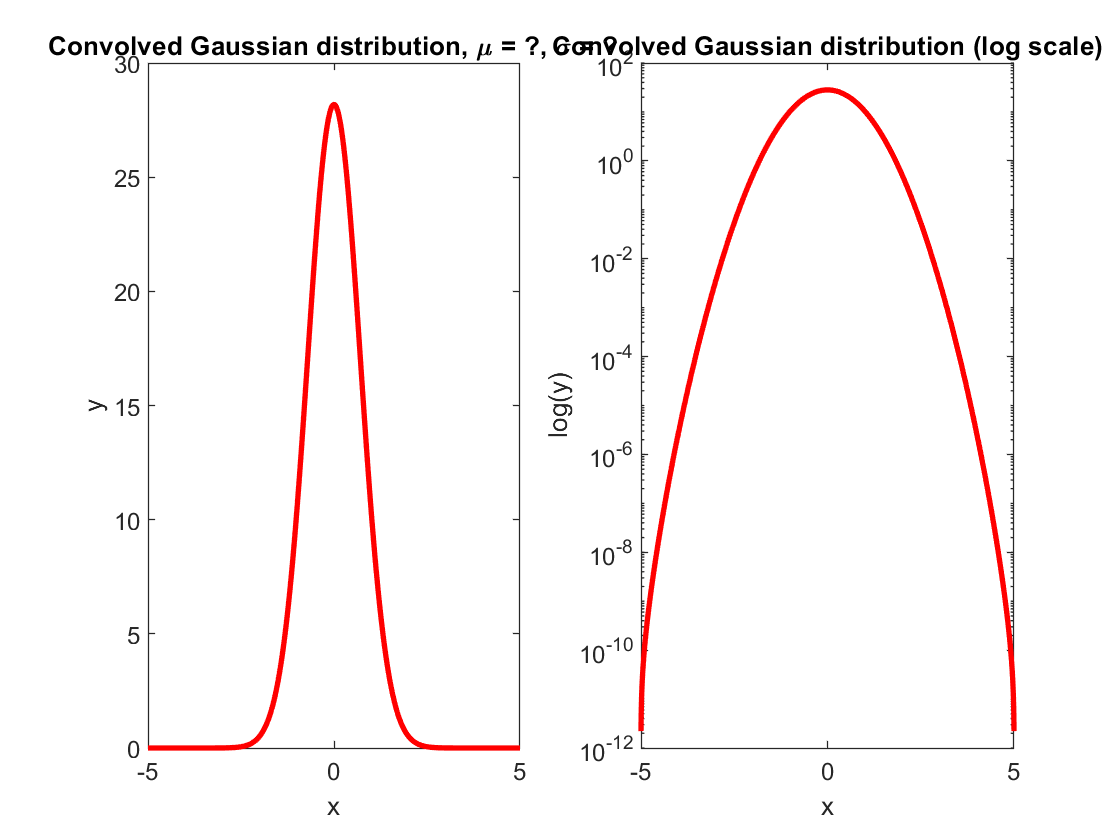

convolved_gaussian = conv(ys, ys);
clf;
new_xs = linspace(-5, 5, length(convolved_gaussian));

subplot(1, 2, 1);
plot(new_xs, convolved_gaussian, 'r-', 'LineWidth', 2)
title('Convolved Gaussian distribution');
xlabel('x');
ylabel('y');

subplot(1, 2, 2);
semilogy(new_xs, convolved_gaussian, 'r-', 'LineWidth', 2)
title('Convolved Gaussian distribution (log scale)');
xlabel('x');
ylabel('log(y)');

The mean of this convolved distribution is still zero, and the standard deviation has gotten smaller. This means, when integrating a signal over time, one should expect their standard deviation to decrease according to how long they average the signal for. In other words, the longer one averages or integrates a signal over time, the more precise the signal will be and the less the background may contribute to the error of the experiment.